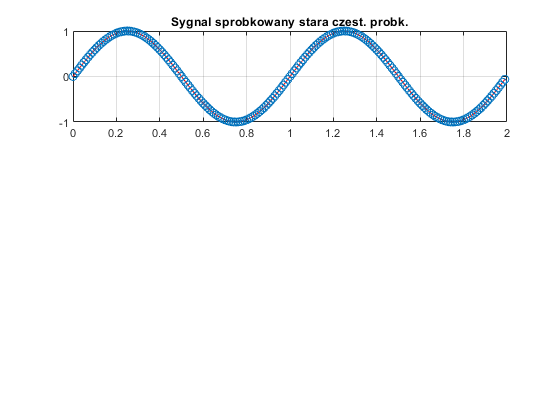

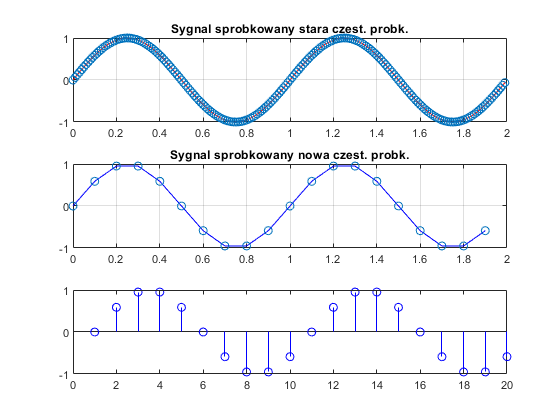

z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


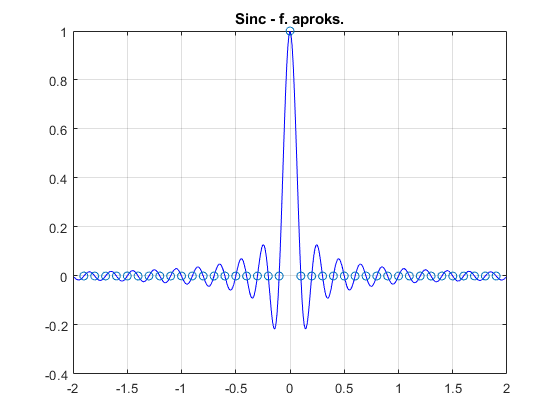

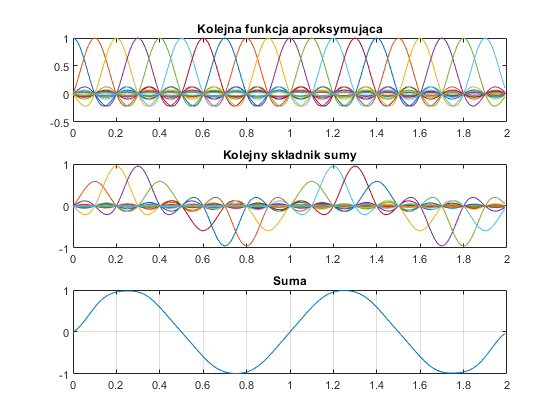

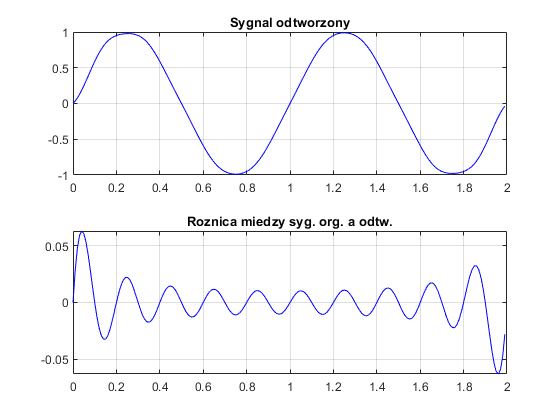

% Rodzial 4 Zielniski

%                       Mateusz Krupnik
clear all; clf;
% Generowanie przebiegu
fx = 1;     % częstotliwość sygnału [Hz]
fps = 100;  % stara częstotliwość próbkowania [Hz]
N = 200;    % liczba próbek sygnału spróbkowanego z częstotliwością fps (stara)
K = 10;     % ile razy zmniejszyć częstotliwość próbkowania

% Generacja sygnalu
dts = 1/fps;            % stary okres probkowania
ts = 0:dts:(N-1)*dts;
xs = sin(2*pi*fx*ts);   % sprobkowany
% Generacja wykresu
subplot(3,1,1)
plot(ts, xs, 'r', ts, xs, 'o'); grid; title('Sygnal sprobkowany stara czest. probk.');

fpn = fps/K;
xn = xs(1:K:length(xs)); M = length(xn); % sprobkowany nowa czestotliwoscia
dtn = K*dts; tn = 0:dtn:(M-1)*dtn;
% Generacja wykresu
subplot(3,1,2)
plot(tn, xn, 'b', tn, xn, 'o'); grid; title('Sygnal sprobkowany nowa czest. probk.');hold on;
subplot(3,1,3)
stem(xn, 'b');

% Rekonstrukcja sygnalu
% Funkcja aproks.
t = -(N-1)*dts : dts : (N-1)*dts;   % czas trwania f. aproks
f = 1/(2*dtn);                      % czestotliwosc zer w f. aproks
fun_aproks = sin(2*pi*f*t)./(2*pi*f*t); %funkcja sinc=sinx/x
fun_aproks(N) = 1;  % w wartosci 0 mamy 0/0
tz = [-fliplr(tn) tn(2:M)];
z = [zeros(1, M-1) 1 zeros(1, M-1)] % delta diraca

% Wykres
figure()
plot(t, fun_aproks, 'b', tz, z, 'o'); grid; title('Sinc - f. aproks.');

% Aproksymacja
y = zeros(1, N);        % prealokacja
ty = 0:dts:(N-1)*dts;   % wektor czasu
figure()
for k=1:M
    % funkcja aproksymujaca
    fun_aproks1 = fun_aproks( N-(k-1)*K : (2*N-1)-(k-1)*K);
    y1 = xn(1, k)*fun_aproks1;  % probka*f.aprosk
    y = y + y1;                 % sumowanie
    % wykres
    subplot(311); plot(ty, fun_aproks1); grid; hold on; title('Kolejna funkcja aproksymująca');
    subplot(312); plot(ty,y1); grid; title('Kolejny składnik sumy'); hold on;
end
% Wykres calości
subplot(313); plot(ty,y); grid; title('Suma skladowych');

% Wykres porownawczy
figure()
subplot(211); plot(ty, y, 'b'); grid; title('Sygnal odtworzony');
subplot(212); plot(ty, xs(1:N)-y(1:N), 'b'); grid; title('Roznica miedzy syg. org. a odtw.');